# Chapter 2, Section 2 (Part 1)

We use the phrase "linear combination" several times in our last activities, but here we will give it a formal definiton.

**Definition: **Let $S={\vec v_1,\vec v_2,\ldots,\vec v_n}$ be a set of vectors in $R^n$, and let $c_1, c_2,\ldots,c_n$ be scalar elements of $R$. An expression of the form


$$c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n$$


is called a **linear combination** of the vectors in $S$.

# Example #1

Show that the vector


$$\vec v=\pmatrix{3\cr 6\cr 2}$$


can be written as a linear combination of the vectors


$$\vec v_1=\pmatrix{2\cr 2\cr 0},\qquad \vec v_2=\pmatrix{-1\cr 2\cr 0},\qquad\text{and}\qquad \vec v_3=\pmatrix{0\cr 0\cr 1}$$


**Solution:** Let's write $\vec v$ as a linear combination of the vectors $\vec v_1$, $\vec v_2$, and $\vec v_3$.


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+c_3\vec v_3&=&\vec v\\
c_1\pmatrix{2\cr 2\cr 0}+c_2\pmatrix{-1\cr 2\cr 0}+c_3\pmatrix{0\cr 0\cr 1}&=&\pmatrix{3\cr 6\cr 2}\\
\pmatrix{2c_1-c_2\cr 2c_1+2c_2\cr c_3}&=&\pmatrix{3\cr 6\cr 2}
\end{array}$$
 

If we equate the components of these two equal vectors, we get the following system of linear equations.


$$\begin{array}{rcl}
2c_1-c_2&=&3\\
2c_1+2c_2&=&6\\
c_3&=&2
\end{array}$$


We can set up the augmented matrix for this system and row reduce.


$$\pmatrix{2 & -1 & 0 & 3\cr 2 & 2 & 0 & 6\cr 0 & 0 & 1 & 2}\ \matrix{~\cr R_2-R1\cr ~}\qquad\longrightarrow\qquad\pmatrix{2 & -1 & 0 & 3\cr 0 &3 & 0 & 3\cr 0 & 0 & 1 & 2}$$


We can check this step with Matlab.

A=[2 -1 0 3;2 2 0 6;0 0 1 2];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-r1;r3]

A =      2    -1     0     3
     0     3     0     3
     0     0     1     2


Correct. Next,


$$\pmatrix{2 & -1 & 0 & 3\cr 0 &3 & 0 & 3\cr 0 & 0 & 1 & 2}\ \matrix{(1/2)R_1\cr (1/3)R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & -1/2 & 0 & 3/2\cr 0 &1 & 0 & 1\cr 0 & 0 & 1 & 2}$$


We can check this step with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=sym([1/2*r1;1/3*r2;r3])

$$A = \left(\begin{array}{cccc} 1 & -\frac{1}{2} & 0 & \frac{3}{2}\\ 0 & 1 & 0 & 1\\ 0 & 0 & 1 & 2 \end{array}\right)$$

Correct. We have a system of equations:


$$\begin{array}{rcl}
c_1-\frac12c_2&=&\frac32\\
c_2&=&1\\
c_3&=&2
\end{array}$$


If we substitute $c_2=1$ in the first equaton, we get $c_1=2$, so our answer is:


$$2\pmatrix{2\cr 2\cr 0}+1\pmatrix{-1\cr 2 \cr 0}+2\pmatrix{0\cr 0\cr 1}=\pmatrix{3\cr 6 \cr 2}$$


This can be checked with hand-calculations, but let's check it with Matlab.

v1=[2;2;0]; v2=[-1;2;0]; v3=[0;0;1];
2*v1+1*v2+2*v3

ans =      3
     6
     2


Perfect! We got $(3,6,2)^T$. Let's visualize our answer.

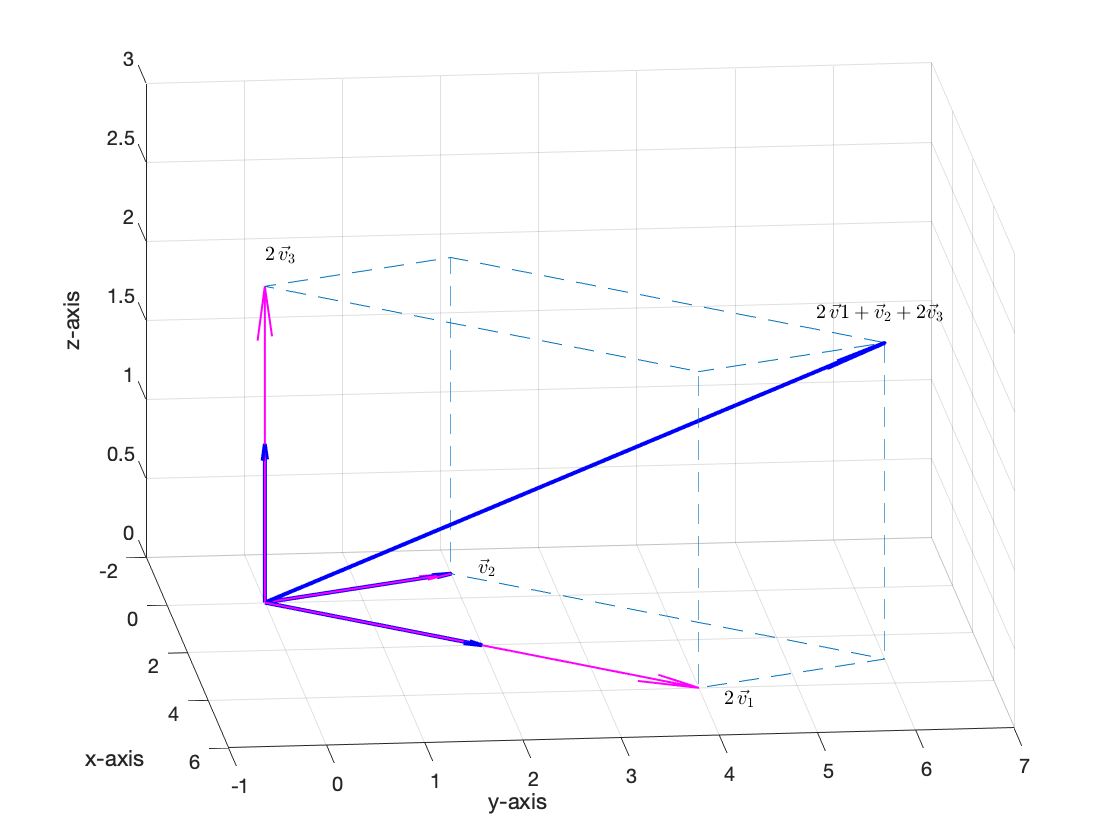

quiver3(0,0,0,2,2,0,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
hold on
quiver3(0,0,0,-1,2,0,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver3(0,0,0,0,0,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver3(0,0,0,3,6,2,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver3(0,0,0,4,4,0,0,'LineWidth',1,'Color','m','MaxHeadSize',0.5)
quiver3(0,0,0,-1,2,0,0,'LineWidth',1,'Color','m','MaxHeadSize',0.5)
quiver3(0,0,0,0,0,2,0,'LineWidth',1,'Color','m','MaxHeadSize',0.5)
line([4,3,-1],[4,6,2],[0,0,0],'LineStyle','--')
line([4,3,-1,0,4],[4,6,2,0,4],[2,2,2,2,2],'LineStyle','--')
line([4,4],[4,4],[0,2],'LineStyle','--')
line([3,3],[6,6],[0,2],'LineStyle','--')
line([-1,-1],[2,2],[0,2],'LineStyle','--')
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
axis([-2,6,-1,7,0,3])
text(4.5,4.2,0,'$2\,\vec v_1$','Interpreter','Latex')
text(-1.2,2.3,0,'$\vec v_2$','Interpreter','Latex')
text(0,0,2.2,'$2\,\vec v_3$','Interpreter','Latex')
text(3,5.3,2.2,'$2\,\vec v1+\vec v_2+2\vec v_3$','Interpreter','Latex')
view(84,22)
hold off

# Example #2

Can the vector


$$\vec v=\pmatrix{1\cr 1\cr 2}$$


can be written as a linear combination of the vectors


$$\vec v_1=\pmatrix{2\cr 0\cr -1},\qquad \vec v_2=\pmatrix{0\cr 3\cr -1},\qquad\text{and}\qquad \vec v_3=\pmatrix{2\cr 3\cr -2}$$


**Solution:** Before we start, let's reveal that your instructor chose $\vec v_3$ as sum of the vectors $\vec v_1$ and $\vec v_2$.  We'll soon see how this affects this example. Let's write $\vec v$ as a linear combination of $\vec v_1$, $\vec v_2$, and $\vec v_3$.


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+c_3\vec v_3&=&\vec v\\
c_1\pmatrix{2\cr 0\cr -1}+c_2\pmatrix{0\cr 3\cr -1}+c_3\pmatrix{2\cr 3\cr -2}&=&\pmatrix{1\cr 1\cr 2}
\end{array}$$


Now, let's manipulate this a bit.


$$\pmatrix{2c_1+2c_3\cr 3c_2+3c_3\cr -c_1-c_2-2c_3}=\pmatrix{1\cr 1\cr 2}$$


If we equate the components of these two vectors, we get the following system of linear equations.


$$\begin{array}{rcl}
2c_1+2c_3&=&1\\
3c_2+3c_3&=&1\\
-c_1-c_2-2c_3&=&1
\end{array}$$


Now we can set up the augmented matrix and row reduce.


$$\pmatrix{2 & 0 & 2 & 1\cr 0 & 3 & 3 & 1\cr -1 & -1 & -2 & 1}\ \matrix{(1/2)R_1\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 1 & 1/2\cr 0 & 3 & 3 & 1\cr -1 & -1 & -2 & 1}$$


We can check this with Matlab.

A=[2 0 2 1;0 3 3 1;-1 -1 -2 1];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=sym([1/2*r1;r2;r3])

$$A = \left(\begin{array}{cccc} 1 & 0 & 1 & \frac{1}{2}\\ 0 & 3 & 3 & 1\\ -1 & -1 & -2 & 1 \end{array}\right)$$

Same answer. Next,


$$\pmatrix{1 & 0 & 1 & 1/2\cr 0 & 3 & 3 & 1\cr -1 & -1 & -2 & 1}\ \matrix{~\cr ~\cr R_3+R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 1 & 1/2\cr 0 & 3 & 3 & 1\cr 0 & -1 & -1 & 3/2}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=sym([r1;r2;r3+r1])

$$A = \left(\begin{array}{cccc} 1 & 0 & 1 & \frac{1}{2}\\ 0 & 3 & 3 & 1\\ 0 & -1 & -1 & \frac{3}{2} \end{array}\right)$$

Same answer. Next,


$$\pmatrix{1 & 0 & 1 & 1/2\cr 0 & 3 & 3 & 1\cr 0 & -1 & -1 & 3/2}\ \matrix{~\cr~\cr R_3+(1/3)R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 1 & 1/2\cr 0 & 3 & 3 & 1\cr 0 & 0 & 0 & 11/6}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=sym([r1;r2;r3+1/3*r2])

$$A = \left(\begin{array}{cccc} 1 & 0 & 1 & \frac{1}{2}\\ 0 & 3 & 3 & 1\\ 0 & 0 & 0 & \frac{11}{6} \end{array}\right)$$

Same answer. Note that the last row of this matrix represents the equation


$$0c_1+0c_2+0c_3=\frac{11}{6}$$


which has no solution. This is an inconsistent system.

# Visualizing Example #2

Why was it not possible to write $\vec v$ as a linear combination of $\vec v_1$, $\vec v_2$ and $\vec v_3$ in Example #2? As stated at the start of the solution, your instructor chose $\vec v_3$ as the sum of vectors $\vec v_1$ and $\vec v_2$. All linear combinations of $\vec v_1$ and $\vec v_2$ line in the plane spanned by the vectors $\vec v_1$ and $\vec v_2$. Let's visualize this. First, let's let $\vec x$ represent an arbitrary linear combination of $\vec v_1$ and $\vec v_2$.


$$\begin{array}{rcl}
\vec x&=&s\,\vec v_1+t\,\vec v_2\\
\pmatrix{x\cr y\cr z}&=&s\pmatrix{2\cr 0\cr -1}+t\pmatrix{0\cr 3\cr -1}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{2s\cr 0\cr -s}+\pmatrix{0\cr 3t\cr -t}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{2s\cr3t\cr-s-t}
\end{array}$$


If we equate the components of these two equal vectors, we get a parametrization of the plane spanned by the vectors $\vec v_1$ and $\vec v_2$.


$$\begin{array}{rcl}
x&=&2s\\
y&=&3t\\
z&=&-s-t
\end{array}$$


Let's choose some values for $s$ and $t$, then use them to create a grid of points.

s=linspace(-1.5,-1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);

Now we calculate $x$, $y$, and $z$, storing the results in X, Y, and Z.

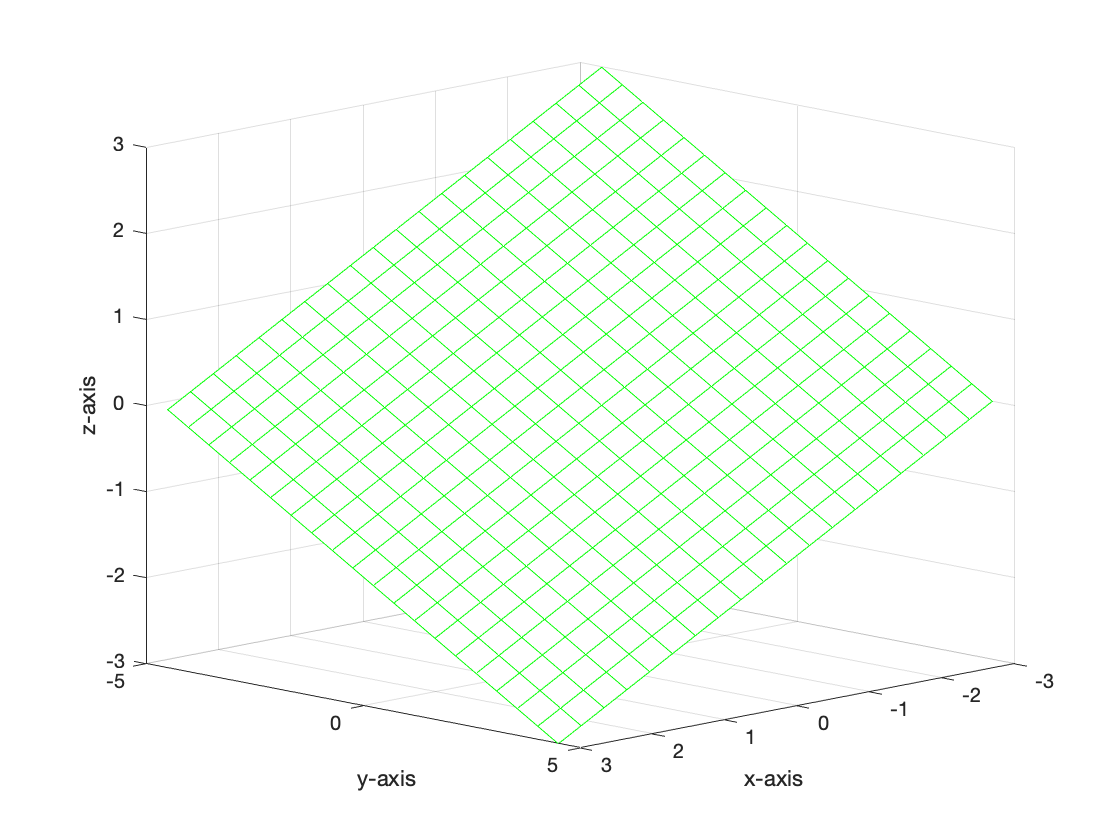

mesh(X,Y,Z,'EdgeColor','g');
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
view(135,13)

Let's add our vectors $\vec v_1$, $\vec v_2$, and $\vec v_3$ to our image.

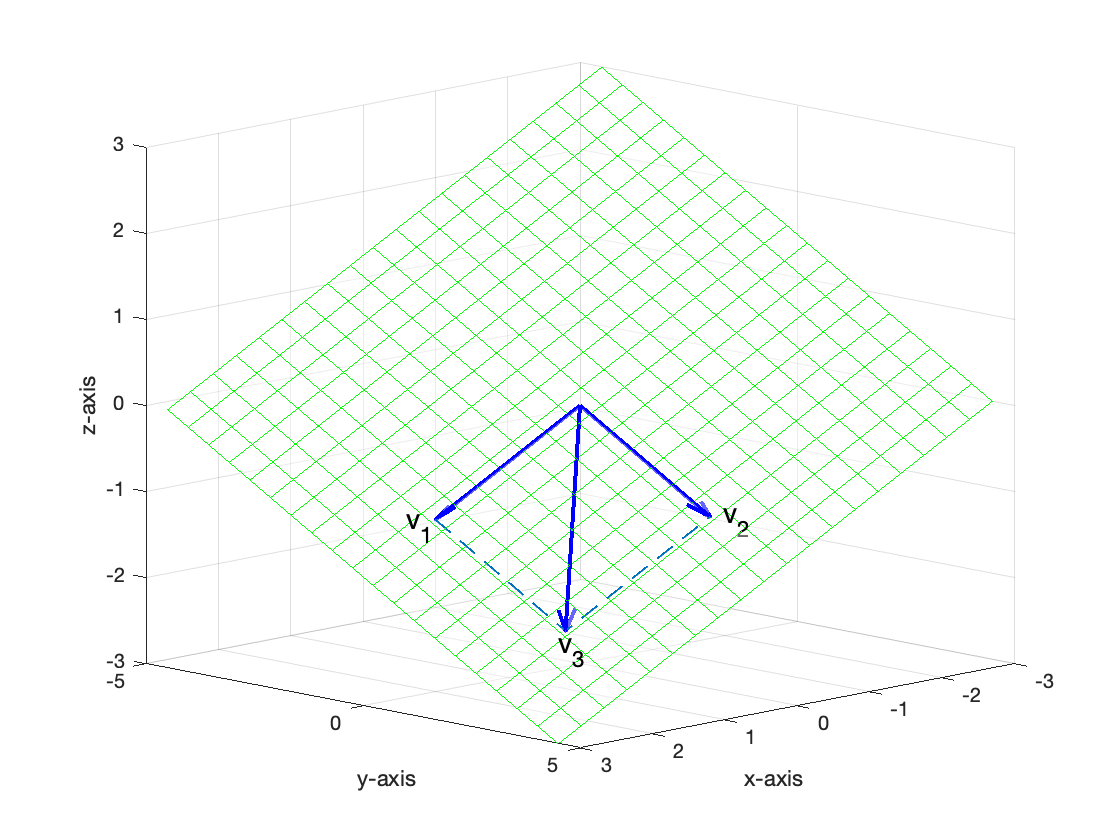

s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=2*S;
Y=3*T;
Z=-S-T;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.4)
hold on
quiver3(0,0,0,2,0,-1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.4)
quiver3(0,0,0,0,3,-1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.4)
quiver3(0,0,0,2,3,-2,0,'LineWidth',2,'Color','b','MaxHeadSize',0.4)
line([2,2,0],[0,3,3],[-1,-2,-1],'LineStyle','--','LineWidth',1)
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
text(2.4,0,-1,'v_1','FontSize',14)
text(0,3.3,-1,'v_2','FontSize',14)
text(2.7,4,-2,'v_3','FontSize',14)
hold off
view(135,13)

Note how $\vec v_3$ is the sum of $\vec v_1$ and $\vec v_2$ by the parallelogram rule. Now, what about the vector $\vec v=(1,1,2)^T$. Our calculations said it could not be written as a linear combination of $\vec v_1$, $\vec v_2$, and $\vec v_3$. Let's add the vector $\vec v$ to our image.

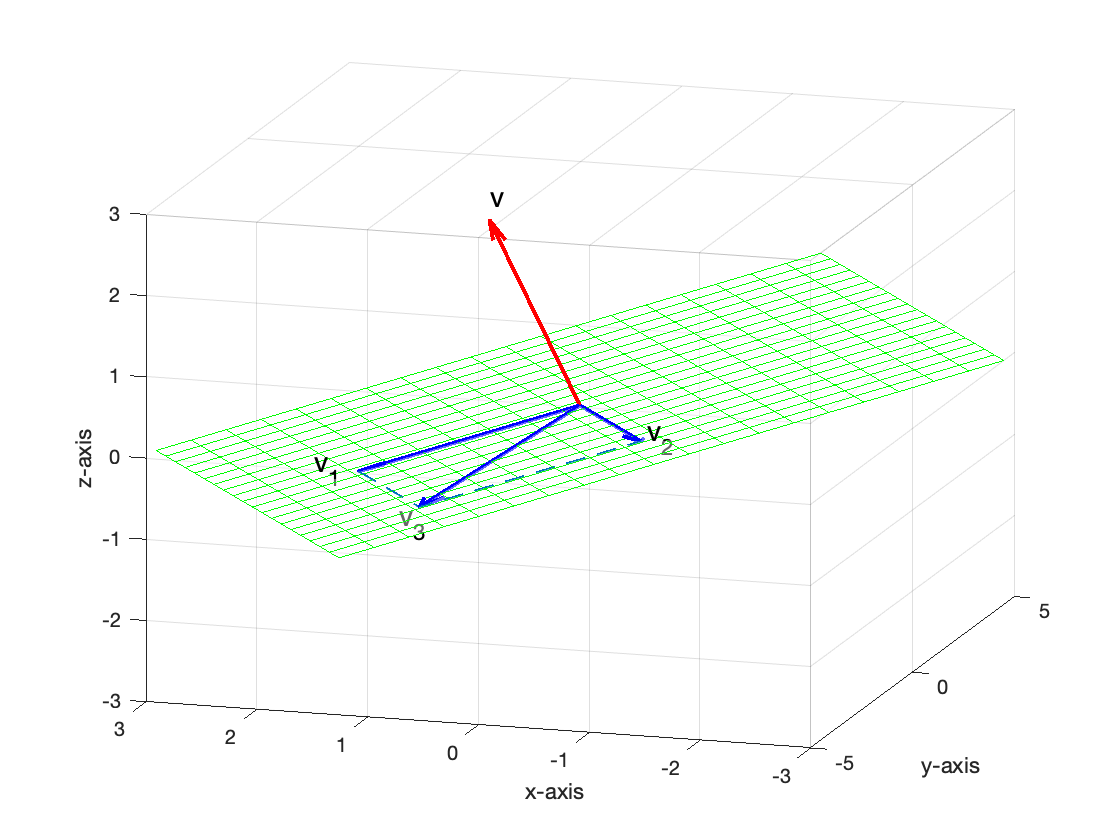

s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=2*S;
Y=3*T;
Z=-S-T;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.4)
hold on
quiver3(0,0,0,2,0,-1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.4)
quiver3(0,0,0,0,3,-1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.4)
quiver3(0,0,0,2,3,-2,0,'LineWidth',2,'Color','b','MaxHeadSize',0.4)
quiver3(0,0,0,1,1,2,0,'LineWidth',2,'Color','r','MaxHeadSize',0.4)
line([2,2,0],[0,3,3],[-1,-2,-1],'LineStyle','--','LineWidth',1)
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
text(2.4,0,-1,'v_1','FontSize',14)
text(0,3.3,-1,'v_2','FontSize',14)
text(2,2,-2,'v_3','FontSize',14)
text(1,1,2.3,'v','FontSize',14)
hold off
view(163,-18)

Note that we have rotated our image to make it clear that the vector $\vec v$ does not lie in the plane spanned by the vectors $\vec v_1$, $\vec v_2$, and $\vec v_3$. That's why $\vec v$ cannot be written as a linear combintation of $\vec v_1$, $\vec v_2$, and $\vec v_3$.  All linear combinations of $\vec v_1$, $\vec v_2$, and $\vec v_3$ must lie in the plane.